% Init

%clears and runs previous groups script
clear all
cd('C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\6. semester\bachelor projekt\Previous work\Bachelor-main\Bachelor-main\Simulation_Bachelor_Project\Matlab\version24-04-2023')
Drone_2M_Code;

Ktrust = 1.2108e-04

droneMass = 0.4800

Dist = 0.6092

TubeDiag = 0.2300

TubeRot = -1.0240

height_test = 3

hoverControl = 360.8320

model='Drone_2M_sim_V2'

model = 'Drone_2M_sim_V2'

model='Drone_2M_sim_V3'

model = 'Drone_2M_sim_V3'

model='Drone_2M_sim_V4_chrs_controller'

model = 'Drone_2M_sim_V4_chrs_controller'

%model='Drone_2M_sim_V5chr_og_vores_controller'
model='Drone_2M_sim_V6_linmod'

model = 'Drone_2M_sim_V6_linmod'

%model='Drone_2M_sim_V7_blackBox'

%init values for added features
yawNoiceVar=0.4

yawNoiceVar = 0.4000

yatd=0;yaal=0;
rtiuse=0;
ratiuse = 0;
pvti=1;
pvtiuse=0;
pati=1;
patiuse=0;
yvImax=100000;
yvImin=-100000;
yvOutMax=10000;
yvOutMin=-10000;
yawvImax=100000;
yawvImin=-100000;
yawvOutMax=10000;
yawvOutMin=-10000;
yaw_D_FB= 0;%1=feedback branch active, 0=not
yaw_D_F= 1;%1=forward branch active, 0=not
yawvtd_F=0.215;
yawval_F=0.3;
stepYaw=0;
stepRoll=0;
stepPitch=0;
rollCalibGain=1;
pitchCalibGain=1;
yawCalibGain=1;
yawV_tau_zero_prefilter=0;
yawV_tau_pole_prefilter=0;
disableWallSensor=0; %disable wall sensor
pitchVelIntLimit=10000;
rollVelIntLimit=10000;
batVolt

batVolt = 22.2000

yawStepSize=10;
rightDeadBandWidthDeg=0;
leftDeadBandWidthDeg=0;
servoUs2Rad

servoUs2Rad = 0.0014

radToDeg=180/pi;
numRollYawFF=1;denumRollYawFF=1;

%Set refference values:
x_ref=0,x_steptime=0

x_ref = 0

x_steptime = 0

y_ref=0,y_steptime=0

y_ref = 0

y_steptime = 0

z_ref=1,z_steptime=0

z_ref = 1

z_steptime = 0

SIM_TIME=30

SIM_TIME = 30

%simout=sim(model,SIM_TIME);

%plotting position data
%{
positionData=simout.logsout.getElement(4).Values.Data;
yawData=simout.logsout.getElement(3).Values.Data;
uYawData=simout.logsout.getElement(2).Values.Data;
yawRefData=simout.logsout.getElement(1).Values.Data;
t=simout.logsout.getElement(4).Values.Time;

plot(t,positionData)
title("Positions Data, with prev groups control values")
legend("z-position","y-position","x-position")
plot(t,[yawData,yawRefData,uYawData])
title("yaw vel. ref vs sim")
legend("yaw vel","ref","yaw-u")
%}


## Control values OLD

%for each controller we have:
%kp=K_P
%td=tau_d
%al=alpha
%ti=tau_i
%iuse=disable/enable integrator

% height velocity
hvkp = 50;
hval = 1;
hvtd = 1;
hvti = 1;
hviuse = 0;
% Height position
h1kp = 1.2; 
h1td = 0.5;
h1al = 1;
h1ti = 1000;
h1iuse = 0; 

% roll velocity
rkp = 0.9539*4; 
rtd = 0.3205;
ral = 0.5;
rti = 1;
rtiuse=0;
% roll angle
rakp = 3.9;
ratd = 0.32;
raal = 0.2;
rati = 100;
ratiuse = 0;

% pitch velocity
pvkp=0.4503*20; % 0.4503
pvtd=0.4428; %0.4428
pval=0.6;
pvti=1;
pvtiuse=0;
% pitch angle
pakp=3.3497; %pakp=3.3497
patd=0.4793;
paal=0.1;
pati=1;
patiuse=0;

%Yaw angle
yakp=2.2791;
yatd=1.0872;
yati=100;
yatiUse=0;
%hvorfor er der ikke nogen alpha???
%Yaw velocity
yawvkp=0.1652;
yawvtd=0.8041;
yawval=0.3;
yawvti=1.5415;
yawvtiUse=0;
%skal integratoren ikke have hoverControl som init cond???

%x vel
xvkp=0.03; %0.1684
xvtd=0.7443;
xval=0.6;
xvti=100;
xvtiUse=0;
%x pos
xkp=1.06741;
xtd=1.5808;
xal=0.1;
xti=100;
xtiUse=1;

%y vel
yvkp=0.1358;
yvtd=0.8433;
yval=0.7;
yvti=100;
yvtiUse=0;
%y pos
ykp=0.5231;
ytd=2.4413;
yal=0.1;
yti=3.8601;
ytiUse=1;


## Control values NEW

%for each controller we have:
%kp=K_P
%td=tau_d
%al=alpha
%ti=tau_i
%iuse=disable/enable integrator

% height velocity
hvkp = 50;%50;
hval = 1;
hvtd = 1;
hvti = 1;
hviuse = 0;
% Height position
h1kp = 2; 
h1td = 0.5;
h1al = 0.2;
h1ti = 1; %
h1iuse = 1; %%%%%%%%%%%%%%%%%%%%%%%%%

% roll velocity
rkp = 1%0.9539;

rkp = 1

rtd = 0.5;%0.3205;
ral = 0.3;
rti = 1;
rtiuse=0.5;
rollVelIntLimit=20;
batVolt=rollVelIntLimit;%20;sets the limit

% roll angle
rakp = 4;%3.9;
ratd = 0;%0.32;
raal = 0;%0.2;
rati = 100;
ratiuse = 0;

% pitch velocity
pvkp=2.5; % 2.5 %4
pvtd=0.15; 
pval=0.2;
pvti=0.23;
pvtiuse=1;
pitchVelIntLimit=10000;
pitch_act_lim=500;%giver en +- output limit
% pitch angle
pakp=0.9; %pakp=0.9 %2
patd=0.5;
paal=0.1;
pati=1;
patiuse=0;

%Yaw angle
yakp=2.2791;
yatd=1.0872;
yati=100;
yatiUse=0;
%hvorfor er der ikke nogen alpha???
%Yaw velocity
yawV_tau_zero_prefilter=0;
yawV_tau_pole_prefilter=0.2;
yawvkp=3.6;%3.6;
yaw_D_FB= 0;%1=feedback branch active, 0=not
yaw_D_FF= 1;%1=forward branch active, 0=not
yawvtd=0.215;
yawval=0.2;
yawvtd_FF=0.215;
yawval_FF=0.2;
yawvti=0.5;%1.5415;
yawvtiUse=1;
yawvImax=50;
yawvImin=-50;
yawvOutMax=   250;
yawvOutMin=-  250;
%skal integratoren ikke have hoverControl som init cond???

%x vel
xvkp=0.1684;
xvtd=0.7443;
xval=0.6;
xvti=100;
xvtiUse=0;
%x pos
xkp=1.06741;
xtd=1.5808;
xal=0.1;
xti=100;
xtiUse=1;

%y vel
yvkp=0.1358;
yvtd=0.8433;
yval=0.7;
yvti=100;
yvtiUse=0;
yvImax=1000; %not used yet
yvImin=-1000;%not used yet
yvOutMax=   100000;%not used yet
yvOutMin=-  100000;%not used yet
%y pos
ykp=0.5231; 
ytd=2.4413;
yal=0.1;
yti=3.8601;
ytiUse=1;

%simulating with new control values
yvkp=0;xvkp=0;yakp=0;%disable position controller
%hvkp=0%disable height controller
rollCalibGain=1;%calibrerings gain
pitchCalibGain=1;%calibrerings gain
yawCalibGain=1;%calibrerings gain 1/10
disableWallSensor=0; %disable wall sensor
stepYaw=0;      yawStepSize=10;
stepRoll=0;     rollStepSize=20;
stepPitch=0;    pitchStepSize=15;
stepServo=0;    servoStepSize=deg2rad(60);

enableRollToYaw=0; rollToYawTune=1 %enable cross coupling

rollToYawTune = 1

servoAngleFeedBack=0; calibServo=0.7 %0.7

calibServo = 0.7000

rightDeadBandWidthDeg=0;%10;
leftDeadBandWidthDeg=0;%15;
noiseOn=0;      yawNoiceVar=13.4;
servoTimesSlower=300;%makes the servo's x times slower;Defualt=1;

bodyMass = 1.5; % drone weight (with no motors) [kg]
propellerMass =40e-3;
motorMass = 200e-3; % motor mass [kg]
droneMass = bodyMass + motorCount*(motorMass + propellerMass)

droneMass = 1.9800

batteryMass = 0.452; % single battery %392g %0.452
batteryPositionOffset=2/100; %in meters
rightDeadBandWidthDeg=rightDeadBandWidthDeg*(1-stepServo)

rightDeadBandWidthDeg = 0

leftDeadBandWidthDeg=leftDeadBandWidthDeg*(1-stepServo)

leftDeadBandWidthDeg = 0


SIM_TIME=15

SIM_TIME = 15

model='Drone_2M_sim_V6_linmod'

model = 'Drone_2M_sim_V6_linmod'

%model='Drone_2M_sim_V8_OnlyForReport'
%model='Drone_2M_sim_V4_chrs_controller'
simout=sim(model,SIM_TIME); %model='Drone_2M_sim_V6_linmod'

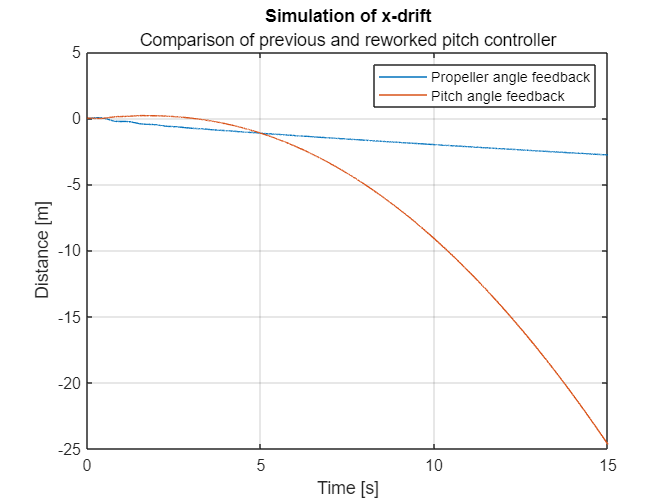

%plotting position data
clf
positionData2=simout.logsout.getElement("Position").Values.Data;
t=simout.logsout.getElement("Position").Values.Time;
plot(t(1:15071),[positionData(1:15071,3),positionData2(:,3)])
title("Simulation of x-drift","Comparison of previous and reworked pitch controller")
legend("Propeller angle feedback","Pitch angle feedback")
xlabel('Time [s]');
ylabel('Distance [m]')
grid on

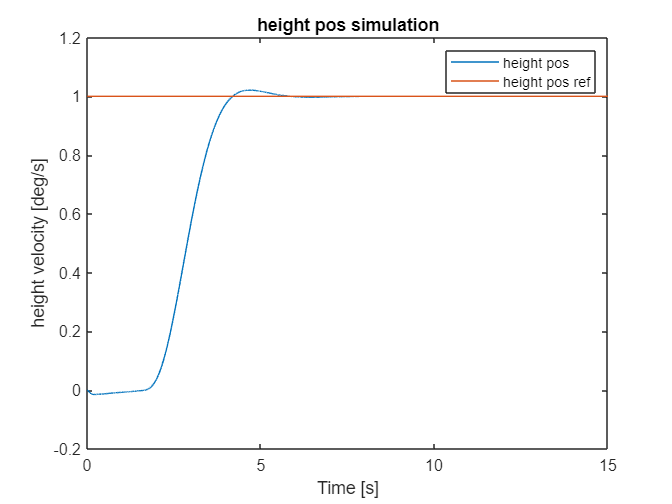


%height
heightData=simout.logsout.getElement("height pos").Values.Data;
uheightData=simout.logsout.getElement("heightCtrl_u").Values.Data;
heightRefData=simout.logsout.getElement("height ref").Values.Data;
plot(t,[heightData,heightRefData])
title("height pos simulation")
legend("height pos","height pos ref")
xlabel('Time [s]');
ylabel('height velocity [deg/s]')

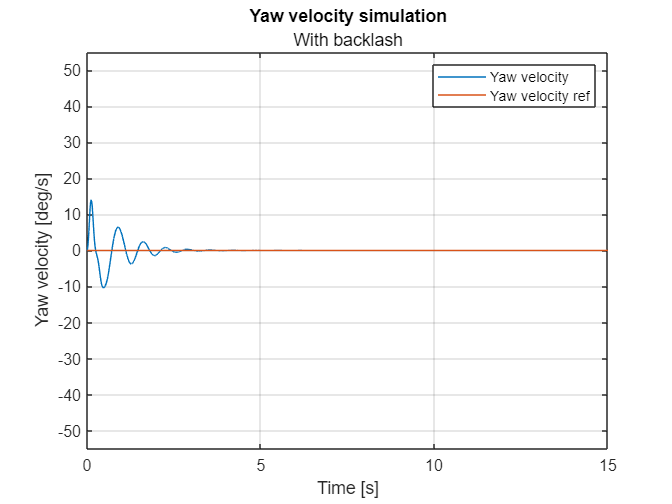


%yaw
uYawData=simout.logsout.getElement("Yaw mixer").Values.Data;
yawData=simout.logsout.getElement("Yaw velocity").Values.Data;
yawRefData=simout.logsout.getElement("Yaw ref").Values.Data;
plot(t,[yawData,yawRefData])
title("Yaw velocity simulation","With backlash")
legend("Yaw velocity","Yaw velocity ref")
xlabel('Time [s]');
ylabel('Yaw velocity [deg/s]')
ylim([-55 55])
yawStep10=yawData;
grid on

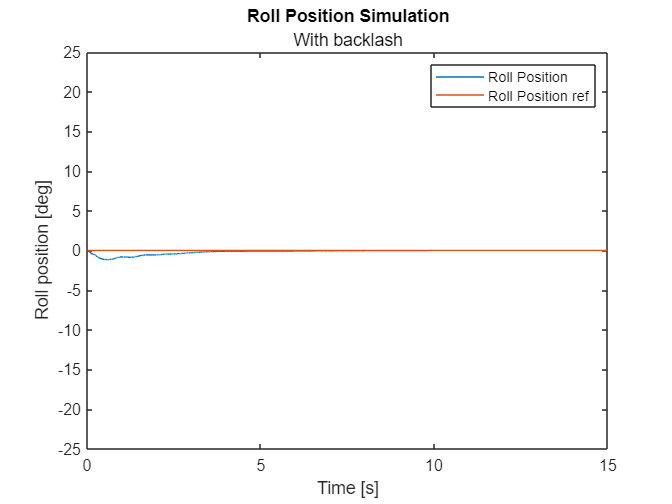

%integratoren gør det værre
%mixer skal gå op til 400

%roll
rollData=simout.logsout.getElement("Roll ang").Values.Data;
urollData=simout.logsout.getElement("u-roll").Values.Data;
rollRefData=simout.logsout.getElement("roll deg ref").Values.Data;
plot(t,[rollData,rollRefData])
title("Roll Position Simulation", "With backlash")
legend("Roll Position","Roll Position ref")
xlabel('Time [s]');
ylabel('Roll position [deg]') 
ylim([-25 25])

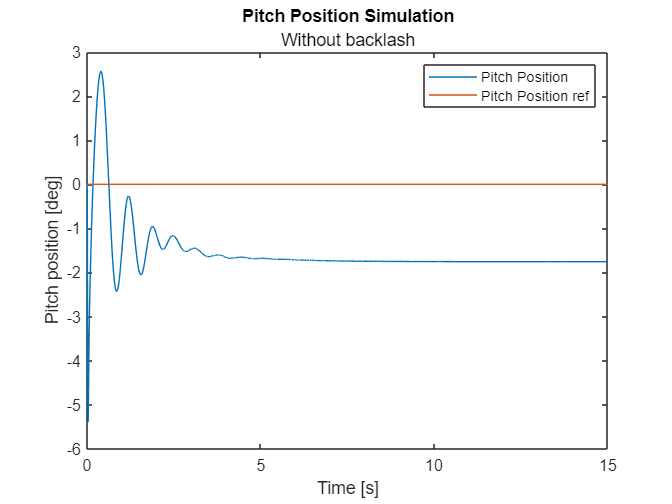


%RollStep20=rollData
%pitch
%pitchData=simout.logsout.getElement("pitch deg").Values.Data;
pitchservoDeg=simout.logsout.getElement("servoDeg").Values.Data;
pitchservoToGround=simout.logsout.getElement("servoToGround").Values.Data;
pitchData=simout.logsout.getElement("pitch deg").Values.Data;
upitchData=simout.logsout.getElement("u-pitch").Values.Data;
pitchRefData=simout.logsout.getElement("Pitch ref").Values.Data;
plot(t,[pitchservoToGround,pitchRefData])
legend("Pitch Position","Pitch Position ref")
title("Pitch Position Simulation", "Without backlash")
xlabel('Time [s]');
ylabel('Pitch position [deg]') 

%ylim([-10 10])
%+-300 mixer
%pitchStep15=pitchData

%save("stepDataUnlinear.mat","RollStep20","yawStep10","pitchStep15","t")

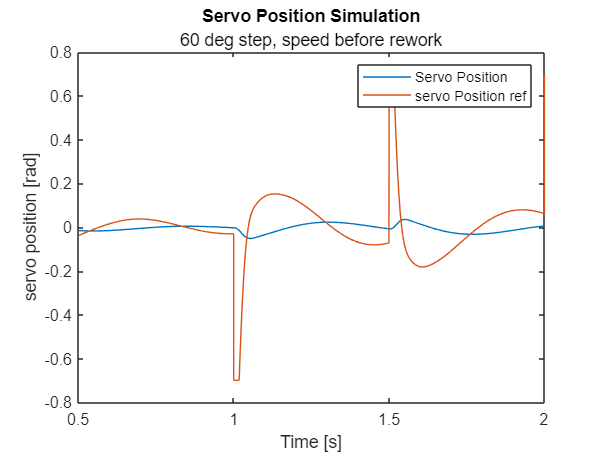

%servo
servoData=simout.logsout.getElement("servo angle").Values.Data;
%uservoData=simout.logsout.getElement("u-servo").Values.Data;
servoRefData=simout.logsout.getElement("servo ref").Values.Data;
servoTime=simout.logsout.getElement("servo ref").Values.Time;
plot(servoTime,[servoData,servoRefData])
legend("Servo Position","servo Position ref")
title("Servo Position Simulation","60 deg step, speed before rework")
xlabel('Time [s]');
ylabel('servo position [rad]') 
xlim([0.5 2])

%roll to yaw:

%model='Drone_2M_sim_V4_chrs_controller'
%plot(t,[yawData,rollRefData])

yawServoTime=simout.logsout.getElement("yaw vel sampled").Values.Time

yawServoTime =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090


yawData=simout.logsout.getElement("yaw vel sampled").Values.Data

yawData =          0
   -0.0560
   -0.0422
   -0.0051
    0.0421
    0.0950
    0.1521
    0.2124
    0.2750
    0.3393


rollRefData=simout.logsout.getElement("roll ref sampled").Values.Data

rollRefData =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


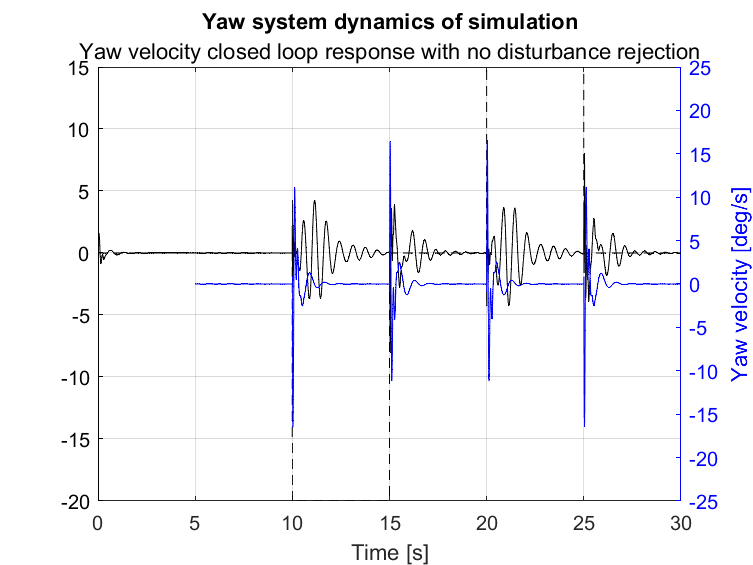

%plot(yawServoTime(1:end-1)-yawServoTime(2:end))
plot(yawServoTime,[yawData,rollRefData])
ylim([-20 15])


idx=yawServoTime>4 & yawServoTime<9

idx = 30001×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


idx=yawServoTime>5

idx = 30001×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


in=rollRefData(idx)

in =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


out=yawData(idx)

out =     0.0007
    0.0007
    0.0007
    0.0007
    0.0007
    0.0007
    0.0007
    0.0007
    0.0007
    0.0007


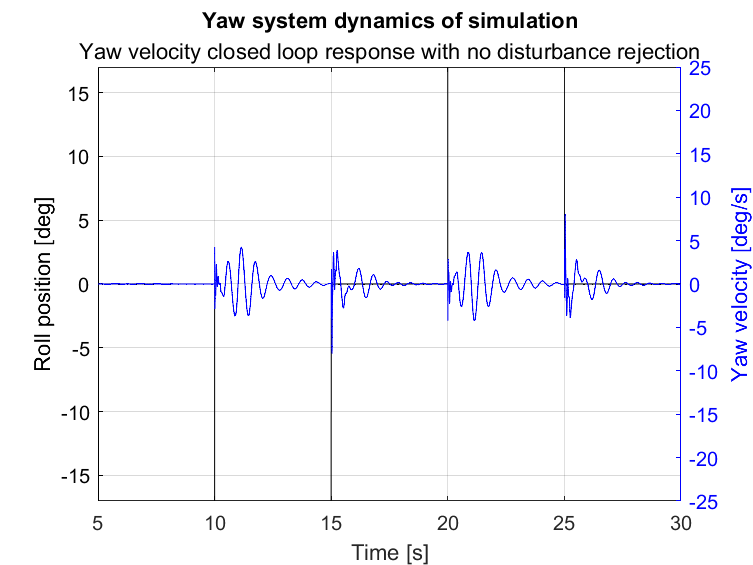

%plot(yawServoTime(yawServoTime>4),[in, out])
%in2=in(yawServoTime<5)
%out2=out(yawServoTime<5)
fig = figure;
left_color = [0 0 0];
right_color = [0 0 1];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis right
plot(yawServoTime(idx),out)
%ylim([-20 15])
title("Yaw system dynamics of simulation","Yaw velocity closed loop response with no disturbance rejection")
xlabel('Time [s]');
ylabel('Yaw velocity [deg/s]')
ylim([-25 25])
grid on
yyaxis left
plot(yawServoTime(idx),in)
ylim([-17 17])
ylabel('Roll position [deg]') 

%legend("Yaw velocity","Roll position ref")


mydata=iddata(out,in,0.001)

mydata =

Time domain data set with 4999 samples.
Sample time: 0.001 seconds              
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


Options = tfestOptions;            
Options.EnforceStability = true;
%poles=6,zeros=4%
poles=8,zeros=6,%for yaw no controller

poles = 8

zeros = 6

TF_fit = tfest(mydata, poles, zeros, Options)

TF_fit =
 
  From input "u1" to output "y1":
          3.983e04 s^6 + 4.649e06 s^5 + 7.435e07 s^4 + 9.068e08 s^3 + 6.502e09 s^2 + 1.242e10 s + 8.334e10
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 215.1 s^7 + 3.138e04 s^6 + 1.028e06 s^5 + 3.11e07 s^4 + 4.727e08 s^3 + 4.956e09 s^2 + 3.365e10 s + 8.029e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 8   Number of zeros: 6
   Number of free coefficients: 15
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.27% (stability enforced)
FPE: 0.0006111, MSE: 0.0006055                     


H_mixer_test=minreal(TF_fit/H_yaw_mixer_to_vel)

H_mixer_test =
 
  From input "y1" to output "y1":
                                                                                                                                
  1.142e05 s^12 + 3.27e07 s^11 + 5.057e09 s^10 + 3.86e11 s^9 + 1.211e13 s^8 + 3.248e14 s^7 + 4.689e15 s^6 + 4.998e16 s^5        
                                                                                                                                
                                                              + 3.606e17 s^4 + 1.328e18 s^3 + 5.43e18 s^2 + 9.991e18 s + 1.48e19
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  s^13 + 755.7 s^12 + 1.659e05 s^11 + 2.601e07

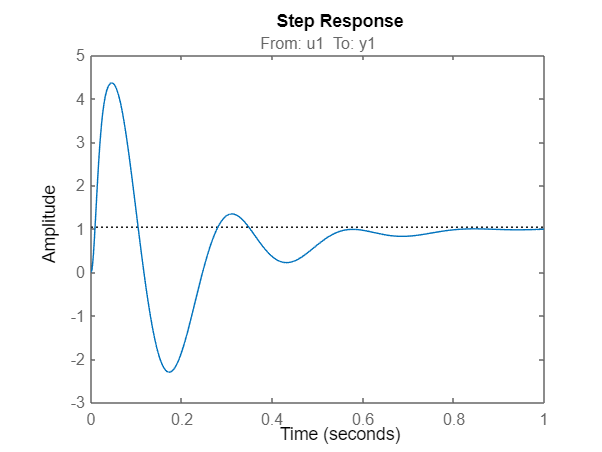

step(TF_fit)

[numRollYawFF denumRollYawFF] = tfdata(H_mixer_test, 'v')

numRollYawFF = 1.0e+19 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0050    0.0361    0.1328    0.5430    0.9991    1.4802


denumRollYawFF = 1.0e+19 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0044    0.0463    0.3506    1.9872    4.5223


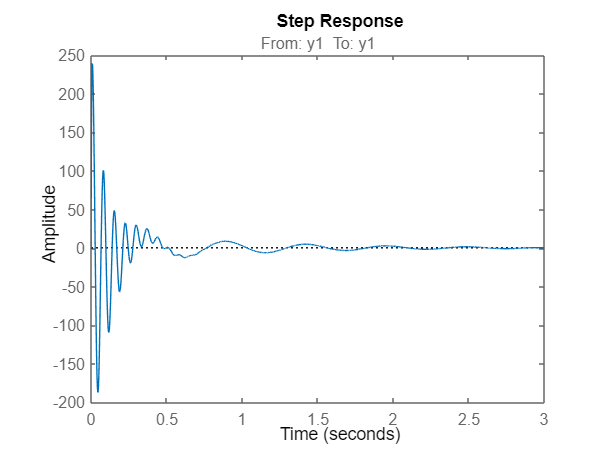

step(H_mixer_test)

pole(H_mixer_test)

ans = 1.0e+02 *

  -5.2066 + 0.0000i
  -0.9099 + 1.2620i
  -0.9099 - 1.2620i
  -0.0882 + 0.8712i
  -0.0882 - 0.8712i
  -0.0643 + 0.2402i
  -0.0643 - 0.2402i
  -0.0113 + 0.1182i
  -0.0113 - 0.1182i
  -0.0321 + 0.1105i


time=(0:0.001:5-0.001)'

time =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090


%save("crossCoupling.mat","in2","out2","time","H_yaw_mixer_to_vel")
%save("crossCouplingV2.mat","H_yaw_mixer_to_vel","H_yaw_induced")
%load("crossCouplingV2.mat")

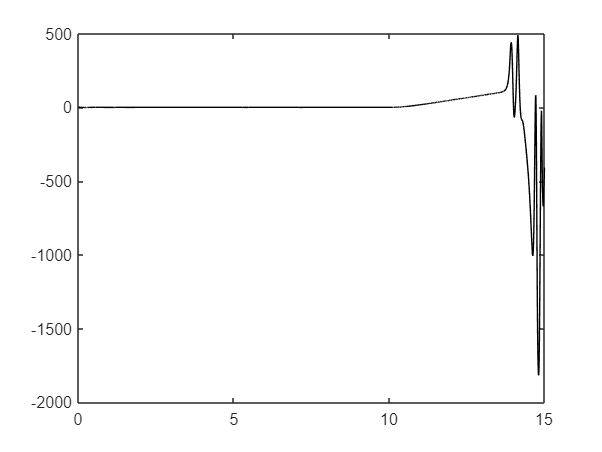

%Mixer to yaw
uYawData=simout.logsout.getElement("Yaw mixer sampled").Values.Data;
yawData=simout.logsout.getElement("yaw vel sampled").Values.Data;
yawTime=simout.logsout.getElement("yaw vel sampled").Values.Time;
clf
plot(yawTime,yawData)


idx=yawTime>4.5 & yawTime<9;
idx=yawTime>9 & yawTime<13.5

idx = 15001×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


input1=uYawData(idx)

input1 =     0.0003
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004


output1=yawData(idx)

output1 =     0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002


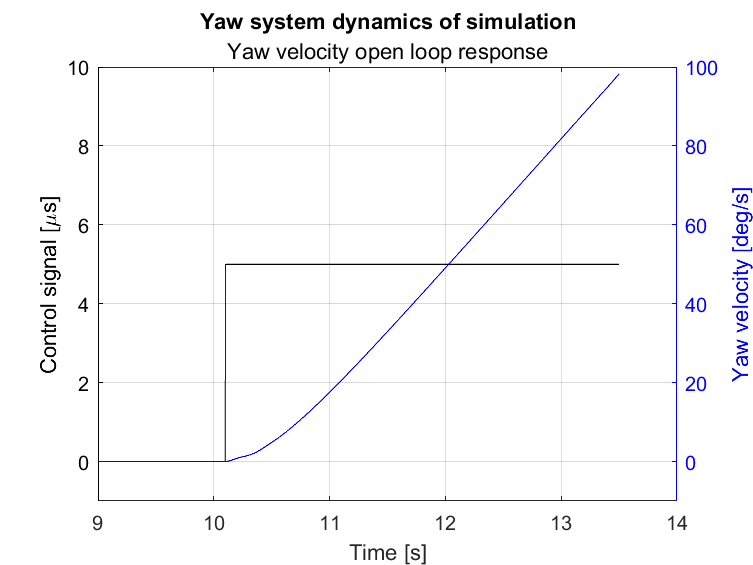


fig = figure;
left_color = [0 0 0];
right_color = [0 0 1];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);
yyaxis right
plot(yawTime(idx),[output1])
ylim padded
ylim([-10 100])
xlabel('Time [s]');
ylabel('Yaw velocity [deg/s]')
yyaxis left
plot(yawTime(idx),[input1])
ylim([-1 10])
%ylim padded
ylabel(['Control signal [\mus]'])

grid on
title("Yaw system dynamics of simulation","Yaw velocity open loop response")

%pole(p2z2)
H_yaw_mixer_to_vel

H_yaw_mixer_to_vel =
 
  From input "u1" to output "y1":
        0.3487 s^5 + 188.5 s^4 + 6349 s^3 + 1.432e06 s^2 + 3.984e06 s + 1.964e08
  ------------------------------------------------------------------------------------
  s^6 + 169.5 s^5 + 2.262e04 s^4 + 4.002e05 s^3 + 1.303e07 s^2 + 3.257e07 s + 6.194e07
 
Name: p6z5
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 6   Number of zeros: 5
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 95.29% (stability enforced)
FPE: 0.1467, MSE: 0.1457                           


H_yaw_mixer_to_vel=p6z5

H_yaw_mixer_to_vel =
 
  From input "u1" to output "y1":
        0.352 s^5 + 225.9 s^4 + 7225 s^3 + 1.663e06 s^2 + 4.118e06 s + 2.281e08
  -----------------------------------------------------------------------------------
  s^6 + 201.8 s^5 + 2.536e04 s^4 + 4.596e05 s^3 + 1.44e07 s^2 + 3.375e07 s + 4.944e05
 
Name: p6z5
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 6   Number of zeros: 5
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.11% (stability enforced)
FPE: 0.01321, MSE: 0.01311                         


zero(H_yaw_mixer_to_vel)

ans = 1.0e+02 *

  -6.2093 + 0.0000i
  -0.0945 + 0.8552i
  -0.0945 - 0.8552i
  -0.0098 + 0.1183i
  -0.0098 - 0.1183i


H_yaw_induced=TF_fit

H_yaw_induced =
 
  From input "u1" to output "y1":
          3.983e04 s^6 + 4.649e06 s^5 + 7.435e07 s^4 + 9.068e08 s^3 + 6.502e09 s^2 + 1.242e10 s + 8.334e10
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 215.1 s^7 + 3.138e04 s^6 + 1.028e06 s^5 + 3.11e07 s^4 + 4.727e08 s^3 + 4.956e09 s^2 + 3.365e10 s + 8.029e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 8   Number of zeros: 6
   Number of free coefficients: 15
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.27% (stability enforced)
FPE: 0.0006111, MSE: 0.0006055                     


H_mixer_test=minreal(H_yaw_induced/H_yaw_mixer_to_vel)

H_mixer_test =
 
  From input "y1" to output "y1":
                                                                                                                                
  1.132e05 s^12 + 3.604e07 s^11 + 5.747e09 s^10 + 4.322e11 s^9 + 1.36e13 s^8 + 3.603e14 s^7 + 5.149e15 s^6 + 5.368e16 s^5       
                                                                                                                                
                                                            + 3.754e17 s^4 + 1.242e18 s^3 + 4.611e18 s^2 + 8.008e18 s + 1.171e17
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  s^13 + 856.9 s^12 + 1.9e05 s^11 + 3.031e07 s

step(H_yaw_induced)

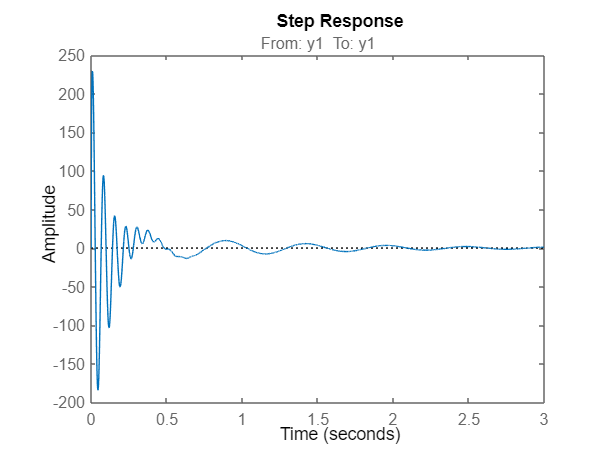

step(H_mixer_test)

step(H_mixer_test*H_yaw_mixer_to_vel)

[numRollYawFF denumRollYawFF] = tfdata(H_mixer_test, 'v')

numRollYawFF = 1.0e+18 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0051    0.0537    0.3754    1.2418    4.6107    8.0082    0.1171


denumRollYawFF = 1.0e+19 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0050    0.0525    0.3985    2.2749    5.2034


%H_yaw_induced_WC=H_yaw_induced
%save("crossCouplingV3.mat","H_yaw_induced","H_yaw_mixer_to_vel","H_mixer_test")
%load("crossCouplingV3.mat")
H_yaw_induced_WC=H_yaw_induced

H_yaw_induced_WC =
 
  From input "u1" to output "y1":
          3.983e04 s^6 + 4.649e06 s^5 + 7.435e07 s^4 + 9.068e08 s^3 + 6.502e09 s^2 + 1.242e10 s + 8.334e10
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 215.1 s^7 + 3.138e04 s^6 + 1.028e06 s^5 + 3.11e07 s^4 + 4.727e08 s^3 + 4.956e09 s^2 + 3.365e10 s + 8.029e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 8   Number of zeros: 6
   Number of free coefficients: 15
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.27% (stability enforced)
FPE: 0.0006111, MSE: 0.0006055                     


%first step i rapport
H_yaw_mixer_to_vel

H_yaw_mixer_to_vel =
 
  From input "u1" to output "y1":
     0.1044 s + 15.33
  -----------------------
  s^2 + 2.332 s + 0.00233
 
Name: p2z1
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 98.84% (stability enforced)
FPE: 0.004215, MSE: 0.00421                        


H_yaw_induced_WC

H_yaw_induced_WC =
 
  From input "u1" to output "y1":
          3.983e04 s^6 + 4.649e06 s^5 + 7.435e07 s^4 + 9.068e08 s^3 + 6.502e09 s^2 + 1.242e10 s + 8.334e10
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 215.1 s^7 + 3.138e04 s^6 + 1.028e06 s^5 + 3.11e07 s^4 + 4.727e08 s^3 + 4.956e09 s^2 + 3.365e10 s + 8.029e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 8   Number of zeros: 6
   Number of free coefficients: 15
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.27% (stability enforced)
FPE: 0.0006111, MSE: 0.0006055                     


step(H_yaw_induced_WC)

H_mixer_test=H_yaw_induced_WC/H_yaw_mixer_to_vel

H_mixer_test =
 
  From input "y1" to output "y1":
                                                                                                                               
   3.983e04 s^8 + 4.742e06 s^7 + 8.52e07 s^6 + 1.08e09 s^5 + 8.617e09 s^4 + 2.758e10 s^3 + 1.123e11 s^2 + 1.944e11 s + 1.942e08
                                                                                                                               
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  0.1044 s^9 + 37.78 s^8 + 6573 s^7 + 5.884e05 s^6 + 1.901e07 s^5 + 5.261e08 s^4 + 7.764e09 s^3 + 7.949e10 s^2 + 5.243e11 s     
                                                                                                                                
                                                 

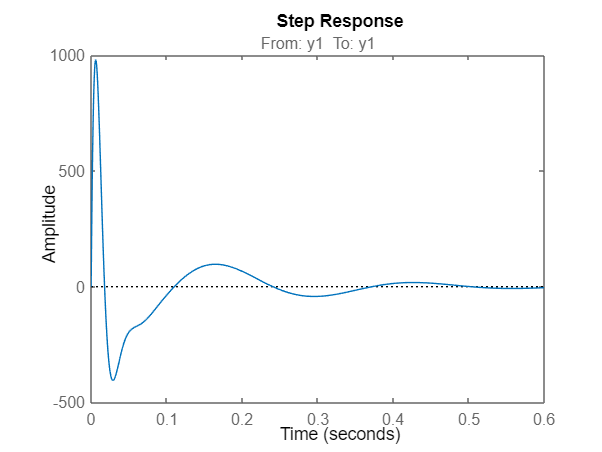

step(H_mixer_test)

[numRollYawFF denumRollYawFF] = tfdata(H_mixer_test, 'v')

numRollYawFF = 1.0e+11 *

         0    0.0000    0.0000    0.0009    0.0108    0.0862    0.2758    1.1231    1.9440    0.0019


denumRollYawFF = 1.0e+12 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0078    0.0795    0.5243    1.2308


%secound step
H_yaw_mixer_to_vel_2,%=p6z5

H_yaw_mixer_to_vel_2 =
 
  From input "u1" to output "y1":
      0.4086 s^5 + 184.3 s^4 + 6591 s^3 + 1.369e06 s^2 + 3.117e06 s + 1.889e08
  ---------------------------------------------------------------------------------
  s^6 + 166 s^5 + 2.138e04 s^4 + 3.678e05 s^3 + 1.194e07 s^2 + 2.343e07 s + 3.27e05
 
Name: p6z5
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 6   Number of zeros: 5
   Number of free coefficients: 12
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.31% (stability enforced)
FPE: 0.01005, MSE: 0.009967                        


H_yaw_induced_WC

H_yaw_induced_WC =
 
  From input "u1" to output "y1":
          3.983e04 s^6 + 4.649e06 s^5 + 7.435e07 s^4 + 9.068e08 s^3 + 6.502e09 s^2 + 1.242e10 s + 8.334e10
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 215.1 s^7 + 3.138e04 s^6 + 1.028e06 s^5 + 3.11e07 s^4 + 4.727e08 s^3 + 4.956e09 s^2 + 3.365e10 s + 8.029e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 8   Number of zeros: 6
   Number of free coefficients: 15
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.27% (stability enforced)
FPE: 0.0006111, MSE: 0.0006055                     


H_mixer_test2=minreal(H_yaw_induced_WC/H_yaw_mixer_to_vel_2)

H_mixer_test2 =
 
  From input "y1" to output "y1":
                                                                                                                                
  9.748e04 s^12 + 2.756e07 s^11 + 4.154e09 s^10 + 3.115e11 s^9 + 9.622e12 s^8 + 2.551e14 s^7 + 3.6e15 s^6 + 3.729e16 s^5        
                                                                                                                                
                                                             + 2.575e17 s^4 + 8.114e17 s^3 + 3.152e18 s^2 + 4.789e18 s + 6.67e16
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  s^13 + 666.1 s^12 + 1.445e05 s^11 + 2.2e07 

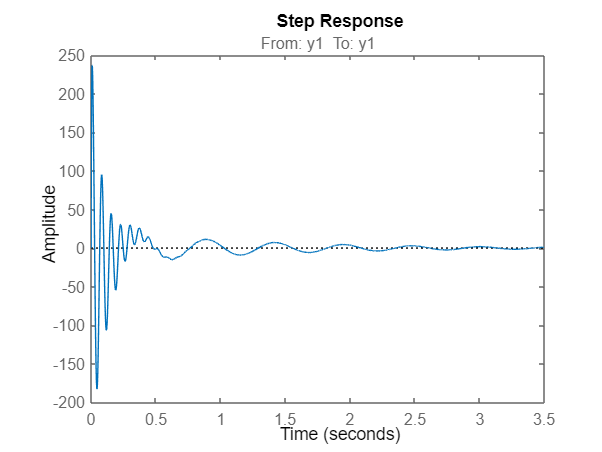

step(H_mixer_test2)

[numRollYawFF denumRollYawFF] = tfdata(H_mixer_test2, 'v')

numRollYawFF = 1.0e+18 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0036    0.0373    0.2575    0.8114    3.1517    4.7893    0.0667


denumRollYawFF = 1.0e+19 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0035    0.0370    0.2817    1.6169    3.7115


%only use one step:
H_yaw_mixer_to_vel_step=p4z2

H_yaw_mixer_to_vel_step =
 
  From input "u1" to output "y1":
          66.62 s^2 + 125.9 s + 9442
  ------------------------------------------
  s^4 + 15.4 s^3 + 609.9 s^2 + 1433 s + 2.79
 
Name: p4z2
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 4   Number of zeros: 2
   Number of free coefficients: 7
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.98% (stability enforced)
FPE: 4.608e-05, MSE: 4.586e-05                     


zero(H_yaw_mixer_to_vel_step)

ans =   -0.9448 +11.8678i
  -0.9448 -11.8678i


pole(H_yaw_mixer_to_vel_step)

ans =   -6.4624 +23.1536i
  -6.4624 -23.1536i
  -2.4779 + 0.0000i
  -0.0019 + 0.0000i


H_yaw_induced_WC

H_yaw_induced_WC =
 
  From input "u1" to output "y1":
          3.983e04 s^6 + 4.649e06 s^5 + 7.435e07 s^4 + 9.068e08 s^3 + 6.502e09 s^2 + 1.242e10 s + 8.334e10
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 215.1 s^7 + 3.138e04 s^6 + 1.028e06 s^5 + 3.11e07 s^4 + 4.727e08 s^3 + 4.956e09 s^2 + 3.365e10 s + 8.029e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 8   Number of zeros: 6
   Number of free coefficients: 15
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.27% (stability enforced)
FPE: 0.0006111, MSE: 0.0006055                     


H_mixer_Step=minreal(H_yaw_induced_WC/H_yaw_mixer_to_vel_step)

H_mixer_Step =
 
  From input "y1" to output "y1":
                                                                                                                                
  597.9 s^10 + 7.899e04 s^9 + 2.556e06 s^8 + 7.422e07 s^7 + 1.088e09 s^6 + 1.159e10 s^5 + 8.316e10 s^4 + 2.729e11 s^3           
                                                                                                                                
                                                                                           + 1.03e12 s^2 + 1.793e12 s + 3.491e09
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  s^10 + 217 s^9 + 3.193e04 s^8 + 1.118e06 s^7

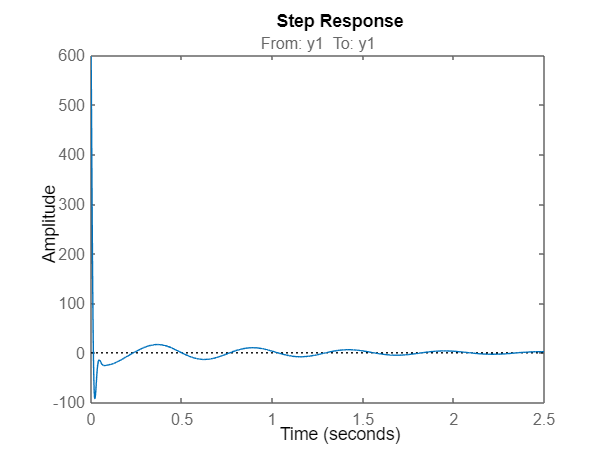

step(H_mixer_Step)

[numRollYawFF denumRollYawFF] = tfdata(H_mixer_Step, 'v')

numRollYawFF = 1.0e+12 *

    0.0000    0.0000    0.0000    0.0001    0.0011    0.0116    0.0832    0.2729    1.0304    1.7932    0.0035


denumRollYawFF = 1.0e+13 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0110    0.0846    0.4921    1.1380


%only use one step V2:
H_yaw_mixer_to_vel_step%=p2z1

H_yaw_mixer_to_vel_step =
 
  From input "u1" to output "y1":
     0.2121 s + 14.96
  -----------------------
  s^2 + 2.237 s + 0.02193
 
Name: p2z1
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.82% (stability enforced)
FPE: 0.003289, MSE: 0.003281                       


zero(H_yaw_mixer_to_vel_step)

ans = -70.5407

pole(H_yaw_mixer_to_vel_step)

ans =    -2.2272
   -0.0098


H_yaw_induced_WC

H_yaw_induced_WC =
 
  From input "u1" to output "y1":
          3.983e04 s^6 + 4.649e06 s^5 + 7.435e07 s^4 + 9.068e08 s^3 + 6.502e09 s^2 + 1.242e10 s + 8.334e10
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 215.1 s^7 + 3.138e04 s^6 + 1.028e06 s^5 + 3.11e07 s^4 + 4.727e08 s^3 + 4.956e09 s^2 + 3.365e10 s + 8.029e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 8   Number of zeros: 6
   Number of free coefficients: 15
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.27% (stability enforced)
FPE: 0.0006111, MSE: 0.0006055                     


H_mixer_Step=minreal(H_yaw_induced_WC/H_yaw_mixer_to_vel_step)

H_mixer_Step =
 
  From input "y1" to output "y1":
                                                                                                                                
  1.878e05 s^8 + 2.234e07 s^7 + 3.996e08 s^6 + 5.061e09 s^5 + 4.023e10 s^4 + 1.272e11 s^3 + 5.246e11 s^2 + 8.803e11 s + 8.615e09
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  s^9 + 285.7 s^8 + 4.656e04 s^7 + 3.242e06 s^6 + 1.036e08 s^5 + 2.667e09 s^4 + 3.83e10 s^3 + 3.833e11 s^2 + 2.454e12 s         
                                                                                                                                
                                              

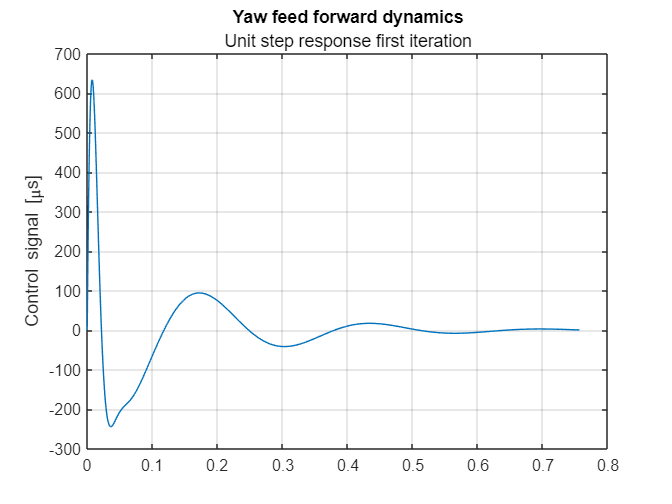

[y,tOut]=step(H_mixer_Step);
clf
plot(tOut,y)
ylabel(['Control signal [\mus]'])
grid on
title("Yaw feed forward dynamics","Unit step response first iteration")

[numRollYawFF denumRollYawFF] = tfdata(H_mixer_Step, 'v')

numRollYawFF = 1.0e+11 *

         0    0.0000    0.0002    0.0040    0.0506    0.4023    1.2723    5.2460    8.8032    0.0862


denumRollYawFF = 1.0e+12 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0027    0.0383    0.3833    2.4541    5.6635


%secound lin, starting with step:
H_yaw_mixer_to_vel_step2=p6z4

H_yaw_mixer_to_vel_step2 =
 
  From input "u1" to output "y1":
               295.9 s^4 + 7320 s^3 + 2.33e06 s^2 + 4.798e06 s + 3.224e08
  ------------------------------------------------------------------------------------
  s^6 + 244.1 s^5 + 3.523e04 s^4 + 6.183e05 s^3 + 2.026e07 s^2 + 4.641e07 s + 7.578e04
 
Name: p6z4
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 6   Number of zeros: 4
   Number of free coefficients: 11
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.2% (stability enforced) 
FPE: 0.01245, MSE: 0.01236                         


H_yaw_induced_WC

H_yaw_induced_WC =
 
  From input "u1" to output "y1":
          3.983e04 s^6 + 4.649e06 s^5 + 7.435e07 s^4 + 9.068e08 s^3 + 6.502e09 s^2 + 1.242e10 s + 8.334e10
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 215.1 s^7 + 3.138e04 s^6 + 1.028e06 s^5 + 3.11e07 s^4 + 4.727e08 s^3 + 4.956e09 s^2 + 3.365e10 s + 8.029e10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 8   Number of zeros: 6
   Number of free coefficients: 15
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.27% (stability enforced)
FPE: 0.0006111, MSE: 0.0006055                     


H_mixer_Step2=minreal(H_yaw_induced_WC/H_yaw_mixer_to_vel_step2)

H_mixer_Step2 =
 
  From input "y1" to output "y1":
                                                                                                                                
  134.6 s^12 + 4.858e04 s^11 + 8.831e06 s^10 + 7.013e08 s^9 + 2.207e10 s^8 + 5.934e11 s^7 + 8.501e12 s^6 + 8.89e13 s^5          
                                                                                                                                
                                                            + 6.234e14 s^4 + 2.045e15 s^3 + 7.657e15 s^2 + 1.307e16 s + 2.134e13
                                                                                                                                
  ------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                
  s^12 + 239.9 s^11 + 4.458e04 s^10 + 3.515e0

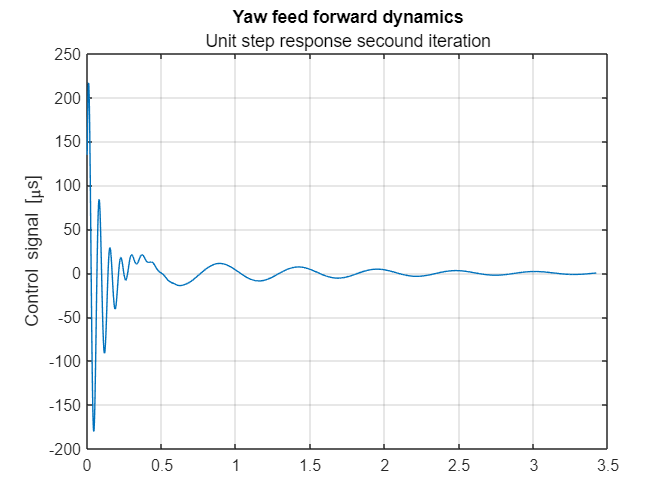

[y,tOut]=step(H_mixer_Step2);
clf
plot(tOut,y)
ylabel(['Control signal [\mus]'])
grid on
title("Yaw feed forward dynamics","Unit step response secound iteration")

[numRollYawFF denumRollYawFF] = tfdata(H_mixer_Step2, 'v')

numRollYawFF = 1.0e+16 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0089    0.0623    0.2045    0.7657    1.3074    0.0021


denumRollYawFF = 1.0e+16 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0081    0.0862    0.6578    3.7965    8.7471


%feed forward med DC
%F=D(0)/G(0)
D0=dcgain(H_yaw_induced_WC)

D0 = 1.0380

G0=dcgain(H_yaw_mixer_to_vel_step2)

G0 = 4.2540e+03

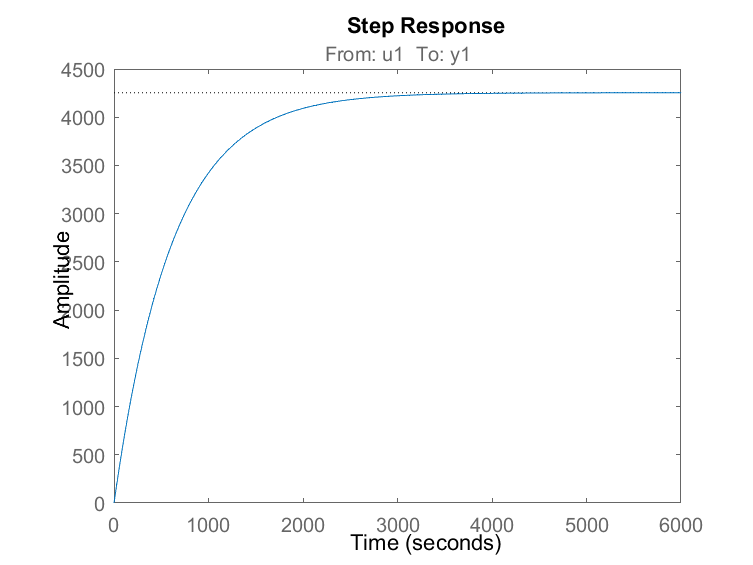

step(H_yaw_mixer_to_vel_step2)